## Experiment 1

Experimental Procedure:

We created a nMOS differential pair with a pMOS current mirror using the ALD1106 and ALD1107 MOSFET arrays. We used a voltage divider to create a desired $V_{2}$ (2.5 V, 3.5 V, and 4.5 V) for each experiment. We used a voltage divider to create a desired $V_{b}$ to change the inversion level of the bias MOSFET (0.7 V for MI and 1.5 V for SI). We attached Ch1 to the gate of M1 in the differential pair and sweeped its voltage from the lower power supply rail to the upper power supply rail. We attatched Ch2 to the drain of M2 to measure $V_{out}$. 

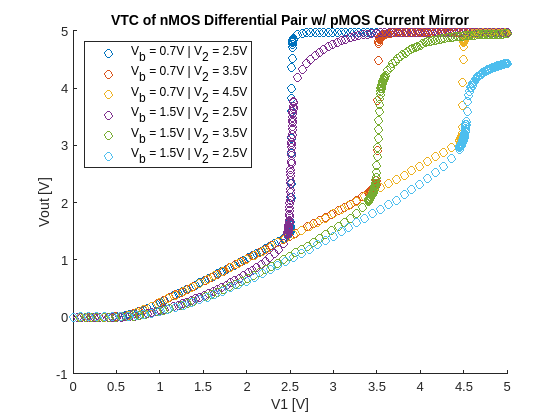

warning('off','all')
clear;
Ex_1 = load('Ex1_MI_0-7_2-5_Vout_NEW.mat');
Ex_2 = load('Ex1_MI_0-7_3-5_Vout_NEW.mat');
Ex_3 = load('Ex1_MI_0-7_4-5_Vout_NEW.mat');
Ex_4 = load('Ex1_SI_1-5_2-5_Vout_NEW.mat');
Ex_5 = load('Ex1_SI_1-5_3-5_Vout_NEW.mat');
Ex_6 = load('Ex1_SI_1-5_4-5_Vout_NEW.mat');

hold on
plot(Ex_1.V1, Ex_1.Vout, 'o')
plot(Ex_2.V1, Ex_2.Vout, 'o')
plot(Ex_3.V1, Ex_3.Vout, 'o')
plot(Ex_4.V1, Ex_4.Vout, 'o')
plot(Ex_5.V1, Ex_5.Vout, 'o')
plot(Ex_6.V1, Ex_6.Vout, 'o')
title("VTC of nMOS Differential Pair w/ pMOS Current Mirror");
xlabel("V1 [V]");
ylabel("Vout [V]");
legend("V_b = 0.7V | V_2 = 2.5V", ...
       "V_b = 0.7V | V_2 = 3.5V", ...
       "V_b = 0.7V | V_2 = 4.5V", ...
       "V_b = 1.5V | V_2 = 2.5V", ...
       "V_b = 1.5V | V_2 = 3.5V", ...
       "V_b = 1.5V | V_2 = 2.5V", ...
       "location", "northwest");

*Lines with a *$V_{b}$* of 0.7 Volts are in moderate inversion while lines with a *$V_{b}$* of 1.5 Volts are in strong inversion.*

The behaviour of the VTC doesn't change substantially when in strong inversion compared to when in moderate inversion. The shape of $V_{out}$ remains very similar, however in strong inversion, the value of $V_{out}$ is slightly less than in moderate inversion.

## Experiment 2

Experimental Procedure:

We used the same setup as we used in Experiment 1. We then sweeped $V_{dm}$ from one rail to another using Ch1 and measured $V_{out}$ using Ch2. WHen the sweeped The output voltage from rail to rail while measuring the output current. Lastly, we swept the differential voltage while measuring the output current.

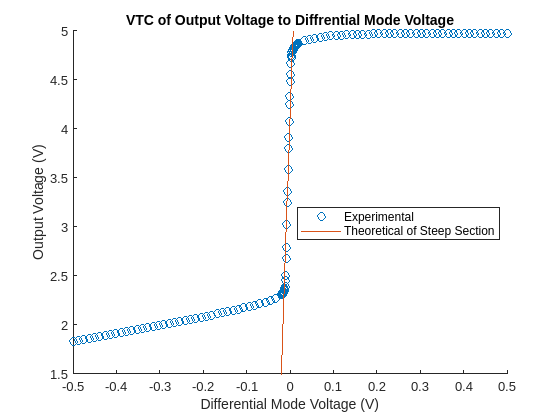

clear; 
clf;
Ex_1 = load('Ex2_1_V2_3-5_Vdm_0-5_NEW.mat');
Ex_2 = load('Ex2_2_V2_3-5_Vdm_0_NEW.mat');
Ex_3 = load('Ex2_3_V2_3-5_Vdm_0-5_NEW.mat');
clf;
hold on
vdm_gain = 128.2;
b = 4.102;
plot(Ex_1.V1, Ex_1.Vout, 'o', 'DisplayName', "Experimental")
plot( Ex_1.V1, vdm_gain .* Ex_1.V1 + b, 'DisplayName', "Theoretical of Steep Section")
ylim([1.5 5])
title("VTC of Output Voltage to Diffrential Mode Voltage")
xlabel("Differential Mode Voltage (V)")
ylabel("Output Voltage (V)")
legend('location', 'best');
hold off

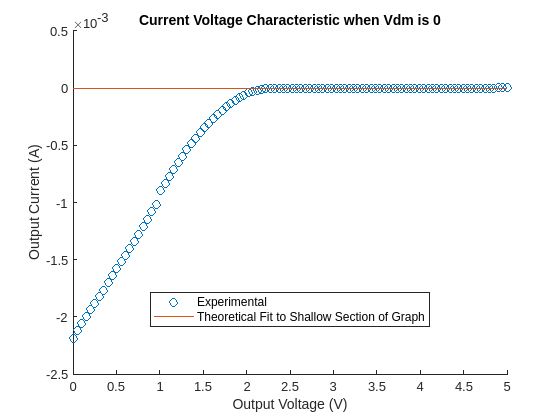

clf;
hold on;
Rout = 8.185e-07;
Rout_copy = 1/Rout;
b =   -3.077e-06;
plot(Ex_2.Ch2, Ex_2.IOut, 'o', 'DisplayName', "Experimental")
plot(Ex_2.Ch2, Rout .* Ex_2.Ch2 + b, 'DisplayName', "Theoretical Fit to Shallow Section of Graph")
title("Current Voltage Characteristic when Vdm is 0")
xlabel("Output Voltage (V)")
ylabel("Output Current (A)")
legend('location', 'best');
hold off

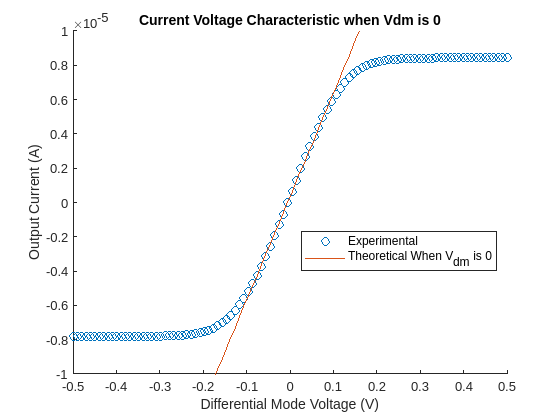

clf;
hold on
incrementalTransconductanceGain =  6.036e-05;
b =  3.441e-07;
plot(Ex_3.V1, -Ex_3.Iout, 'o', 'DisplayName', "Experimental")
plot(Ex_3.V1, incrementalTransconductanceGain .* Ex_3.V1 +b, 'DisplayName', "Theoretical When V_{dm} is 0")
title("Current Voltage Characteristic when Vdm is 0")
xlabel("Differential Mode Voltage (V)")
ylabel("Output Current (A)")
legend('location', 'best');
ylim([-1e-5 1e-5])
hold off


calcedVdmgain = (Rout_copy * incrementalTransconductanceGain)

calcedVdmgain = 73.7447

The calculated differential mode voltage gain for this experiment is 73.8 which is not very close to the measured differential mode voltage gain of 128.2.

## Experiment 3

Experimental Procedure:

We used the same setup as we used in Experiment 1, except we created a unity gain follower by attaching the drain of M2 to the gate of M2. We then sweeped $V_{in}$ from one rail to another using Ch1 and measured $V_{out}$ using Ch2.

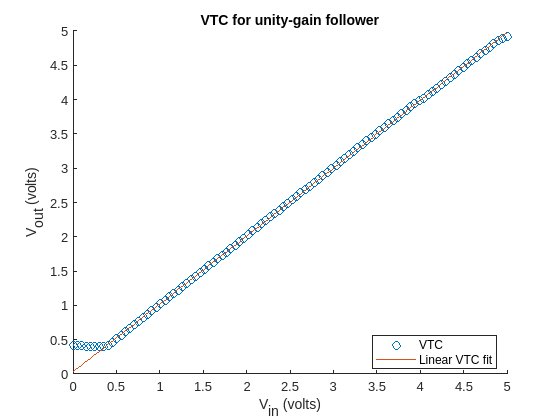

clear;
clf;
load("Ex3_NEW.mat");

hold on;
plot(V1, Vout, "o");

fit_x = linspace(0, 5, 150);
fit_y = 0.99*fit_x + 0.0299;
plot(fit_x, fit_y);

legend("VTC", "Linear VTC fit", "location", "best");
title("VTC for unity-gain follower");
xlabel("V_{in} (volts)");
ylabel("V_{out} (volts)");
hold off;

The incremental gain (slope of the line) around 0.99, which is very close to unity.